clear; 
close all;
clc;

b) Count the number of blocks of each colour 

%segement image by colour in lab colour space 
img = imread('medium.jpg');
lab_img = rgb2lab(img);
ab = lab_img(:,:,2:3);
ab = im2single(ab);
L = imsegkmeans(ab, 11,NumAttempts=11);

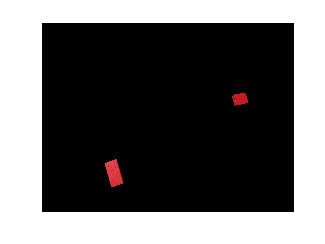

% red shapes 
mask2 = L == 2;
cluster2 = img.*uint8(mask2);
imshow(cluster2)


% preprocess image 
red = preProcessImage(cluster2);

% count number of shapes 
blocks = bwconncomp(red);
disp('The total number of red blocks is  :');

The total number of red blocks is  :


disp(blocks.NumObjects);

     2



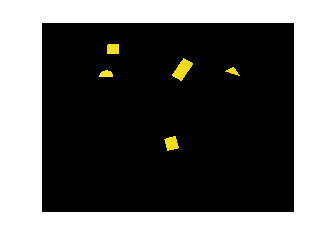

% yellow shapes 
mask3 = L == 3;
cluster3 = img.*uint8(mask3);
imshow(cluster3)


% preprocess image 
yellow = preProcessImage(cluster3);

% count number of shapes 
blocks = bwconncomp(yellow);
disp('The total number of yellow blocks is  :');

The total number of yellow blocks is  :


disp(blocks.NumObjects);

     5



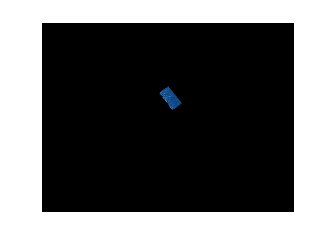

% dark blue shapes
mask4 = L == 4;
cluster4 = img.*uint8(mask4);
imshow(cluster4)


% preprocess image 
dblue = preProcessImage(cluster4);

% count number of shapes 
blocks = bwconncomp(dblue);
disp('The total number of dark blue blocks is  :');

The total number of dark blue blocks is  :


disp(blocks.NumObjects);

     1



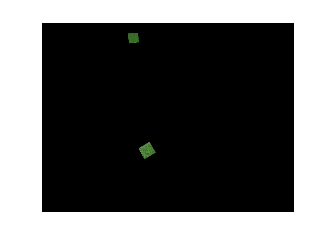

% green shape
mask8 = L == 8;
cluster8 = img.*uint8(mask8);
imshow(cluster8)


% preprocess image 
green = preProcessImage(cluster8);


% count number of shapes 
blocks = bwconncomp(green);
disp('The total number of green blocks is  :');

The total number of green blocks is  :


disp(blocks.NumObjects);

     2



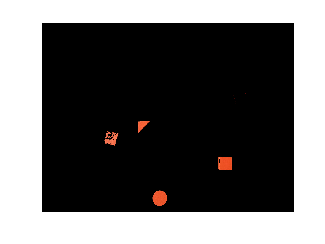

% orange shapes 
mask10 = L == 10;
cluster10 = img.*uint8(mask10);
imshow(cluster10)

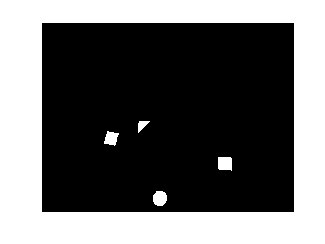


% preprocess image 
orange = preProcessImage(cluster10);
se = strel('disk', 20);
closedImage = imclose(orange, se);
orange = imfill(closedImage, 'holes');
imshow(orange)


% count number of shapes 
blocks = bwconncomp(orange);
disp('The total number of orange blocks is  :');

The total number of orange blocks is  :


disp(blocks.NumObjects);

     4



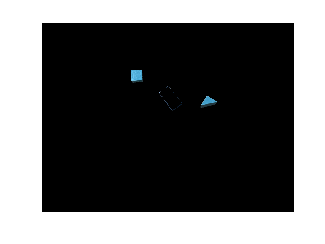

% light blue shapes
mask11 = L == 11;
cluster11 = img.*uint8(mask11);
imshow(cluster11)


% preprocess image 
lblue = preProcessImage(cluster11);
lblue = bwareaopen(lblue,1000);

% count number of shapes 
blocks = bwconncomp(lblue);
disp('The total number of light blue blocks is  :');

The total number of light blue blocks is  :


disp(blocks.NumObjects);

     2



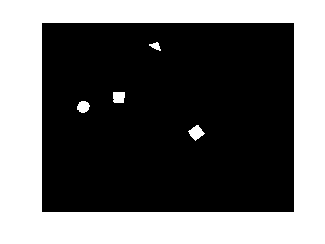

% purple shape 
mask5 = L == 5;
cluster5 = img.*uint8(mask5);
imwrite(cluster5, 'purple.png')

%segement image further to make 2D
i = imread('purple.png');
lab_img = rgb2lab(i);
ab = lab_img(:,:,2:3);
ab = im2single(ab);
L = imsegkmeans(ab, 3,NumAttempts=3);

mask5 = L == 2;
cluster5 = img.*uint8(mask5);

% preprocess image 
purple = preProcessImage(cluster5);
imshow(purple)


% count number of shapes 
blocks = bwconncomp(purple);
disp('The total number of purple blocks is  :');

The total number of purple blocks is  :


disp(blocks.NumObjects);

     4



a) Count the total number of blocks 

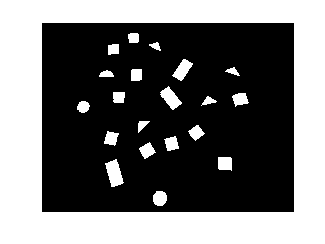

%fuse all coloured shapes into one image 
C = imfuse(yellow,red);
C = imfuse(C,lblue);
C = imfuse(C,dblue);
C = imfuse(C,purple);
C = imfuse(C,green);
C = imfuse(C,orange);

% preprocess image 
BW3 = preProcessImage(C);
imshow(BW3)


 % count number of shapes 
blocks = bwconncomp(BW3);
disp('The total number of blocks is  :');

The total number of blocks is  :


disp(blocks.NumObjects);

    20



c) Count number of blocks of each shape

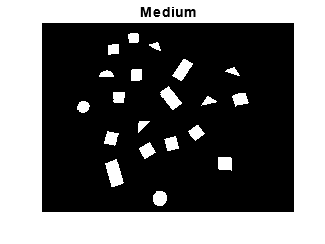

BW = BW3;
shapeStruct = classifyBlocks(BW);
imshow(BW);
title('Medium');

disp('The total number of blocks of each shape is   :')

The total number of blocks of each shape is   :


disp(shapeStruct);

        Circle: 1
     Rectangle: 3
    Semicircle: 2
        Square: 10
      Triangle: 4



d) Number of blocks of each shape of the same colour 

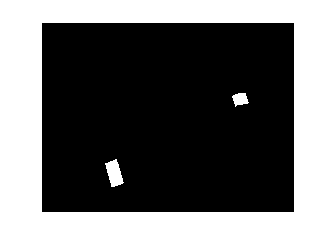

% red 
BW = red;
imshow(red)

shapeStruct = classifyBlocks(BW);
disp('The total number of blocks of each shape that are red are   :')

The total number of blocks of each shape that are red are   :


disp(shapeStruct);

    Rectangle: 1
       Square: 1



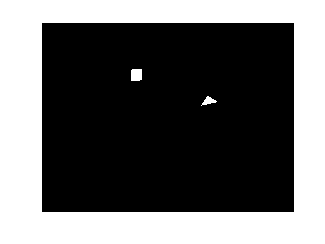

% light blue
BW = lblue;
imshow(BW)

shapeStruct = classifyBlocks(BW);
disp('The total number of blocks of each shape that are light blue are   :')

The total number of blocks of each shape that are light blue are   :


disp(shapeStruct);

      Square: 1
    Triangle: 1



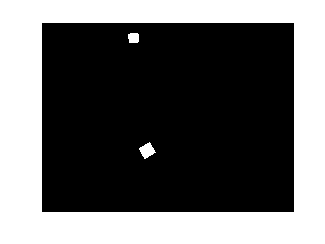

% green 
BW = green;
imshow(BW)

shapeStruct = classifyBlocks(BW);
disp('The total number of blocks of each shape that are green are   :')

The total number of blocks of each shape that are green are   :


disp(shapeStruct);

    Square: 2



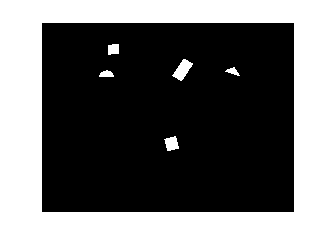

% yellow
BW = yellow;
imshow(BW)

shapeStruct = classifyBlocks(BW);
disp('The total number of blocks of each shape that are yellow are   :')

The total number of blocks of each shape that are yellow are   :


disp(shapeStruct);

     Rectangle: 1
    Semicircle: 1
        Square: 2
      Triangle: 1



% purple
BW = purple;
imshow(BW)

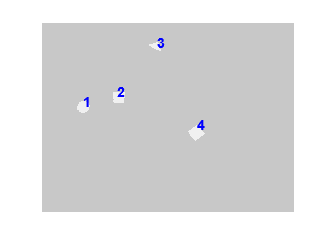

vislabels(BW)

shapeStruct = classifyBlocks(BW);
disp('The total number of blocks of each shape that are purple are   :')

The total number of blocks of each shape that are purple are   :


disp(shapeStruct);

    Semicircle: 1
        Square: 2
      Triangle: 1



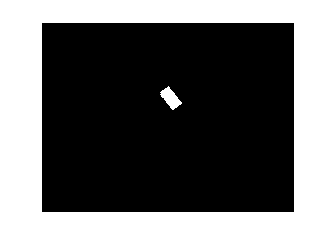

% dark blue 
BW = dblue;
imshow(BW)

shapeStruct = classifyBlocks(BW);
disp('The total number of blocks of each shape that are dark blue are   :')

The total number of blocks of each shape that are dark blue are   :


disp(shapeStruct);

    Rectangle: 1



% orange 
BW = orange;
imshow(BW)

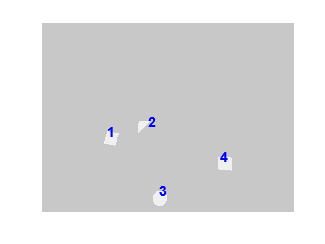

vislabels(BW)

shapeStruct = classifyBlocks(BW);
disp('The total number of blocks of each shape that are orange are   :')

The total number of blocks of each shape that are orange are   :


disp(shapeStruct);

      Circle: 1
      Square: 2
    Triangle: 1



function new_img = preProcessImage(img)
    img_gray = rgb2gray(img);
    BW1 = imbinarize(img_gray);
    BW2 = imfill(BW1,'holes');
    new_img = bwareaopen(BW2,100);
end
function shapeStruct = classifyBlocks(BW)
    shapes = {};
    % identifies boundary of each object (B = boundaries),(L = labels objects and holes),(N = number of objects), 
    [B,L,N] = bwboundaries(BW);

    % calculate properties of all shapes and store in an array 
    stats =  regionprops(L, 'Area', 'Perimeter');
    area = cat(1, stats.Area);
    perimeter = cat(1,stats.Perimeter);

    for k=1:N
        % calculate smallest bounding box of object 
        boundary = B{k};
        [rx,ry,boxArea] = minboundrect( boundary(:,2), boundary(:,1));
        width = sqrt( sum( (rx(2)-rx(1)).^2 + (ry(2)-ry(1)).^2));
        height = sqrt( sum( (rx(2)-rx(3)).^2+ (ry(2)-ry(3)).^2));
        aspectRatio = width/height;

        if aspectRatio > 1
           aspectRatio = height/width;  %make aspect ratio less than unity
        end
        
        p = perimeter(k);
        a = area(k);

        % check if circle
        if ((p.^2)./(4*pi*a)) < 1.1
            shapes{end+1} = 'Circle';
        elseif (area(k)/boxArea) < 0.85
            if (area(k)/boxArea) < 0.6
                shapes{end+1} = 'Triangle';
            else
                shapes{end+1} = 'Semicircle';
            end
        elseif aspectRatio > 0.80
            shapes{end+1} = 'Square';
            
        else
            shapes{end+1} = 'Rectangle';
        end 
    end 
    % display the number of blocks of each shape 
    [uniqueShapes, ~, idx] = unique(shapes);
    shapeCounts = histcounts(idx, 1:length(uniqueShapes)+1);
    shapeStruct = struct();
    for i = 1:length(uniqueShapes)
        shapeStruct.(uniqueShapes{i}) = shapeCounts(i);
    end
end

Comments 

- purple circle is classified incorrectly as a square. Colour clustering may have augmented shape 

- yello semi circle is incorrectly classified as rectange. Should find method to classify semi circle 